clear;clc;
img = imread('lena.bmp')

img = 256×256 uint8 矩阵
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   138   133   134   134   136   132   130   130   131   134   128   127   131   128   128   130   130   128   136   138   142   146   150   150   149   148   143   132   119   111    88    78    65    61    60    66    70    69    73    74    75    74    73    76    73    73    76    73    76    76
   133   133   133   130   134   133   128   125   129   128   128   125  

## subsample-subsample-supersample-supersample

tempimg1 = subsample(img,2)

tempimg1 =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144   139  

tempimg2 = subsample(tempimg1,2)

tempimg2 =    137   138   132   132   130   142   149   119    64    71    78    76    78    79    83    96    98   107    97    99    98   101   103   102   105   105   107   100    99   100   104   100   111   101    98    98    99    98    92    87    76   113   136   121   128   134   126   125   131   133
   129   133   128   129   126   146   149   116    61    64    72    71    71    79    84    93    92    99    99   100    98   101    98    98   102    98    96    98   102    93    99    97    99    97    93    92    98    98    94    83    71   102   129   129   131   132   131   127   130   128
   129   130   127   125   138   144   142   111    59    57    74    71    68    77    83    92    96    95    97   102    99    98   106   100    97    99   101   102    95    98   102   101   101   100    97    93    98    97    95    84    77    82   118   136   134   136   132   130   124   126
   129   133   135   130   143   139   135   115    63    60    73    74    69    76  

tempimg3 = supersample(tempimg2,2)

tempimg3 =    137   137   138   138   132   132   132   132   130   130   142   142   149   149   119   119    64    64    71    71    78    78    76    76    78    78    79    79    83    83    96    96    98    98   107   107    97    97    99    99    98    98   101   101   103   103   102   102   105   105
   137   137   138   138   132   132   132   132   130   130   142   142   149   149   119   119    64    64    71    71    78    78    76    76    78    78    79    79    83    83    96    96    98    98   107   107    97    97    99    99    98    98   101   101   103   103   102   102   105   105
   129   129   133   133   128   128   129   129   126   126   146   146   149   149   116   116    61    61    64    64    72    72    71    71    71    71    79    79    84    84    93    93    92    92    99    99    99    99   100   100    98    98   101   101    98    98    98    98   102   102
   129   129   133   133   128   128   129   129   126   126   146   146   149   149  

image1 = supersample(tempimg3,2)

image1 =    137   137   137   137   138   138   138   138   132   132   132   132   132   132   132   132   130   130   130   130   142   142   142   142   149   149   149   149   119   119   119   119    64    64    64    64    71    71    71    71    78    78    78    78    76    76    76    76    78    78
   137   137   137   137   138   138   138   138   132   132   132   132   132   132   132   132   130   130   130   130   142   142   142   142   149   149   149   149   119   119   119   119    64    64    64    64    71    71    71    71    78    78    78    78    76    76    76    76    78    78
   137   137   137   137   138   138   138   138   132   132   132   132   132   132   132   132   130   130   130   130   142   142   142   142   149   149   149   149   119   119   119   119    64    64    64    64    71    71    71    71    78    78    78    78    76    76    76    76    78    78
   137   137   137   137   138   138   138   138   132   132   132   132   132   132   1

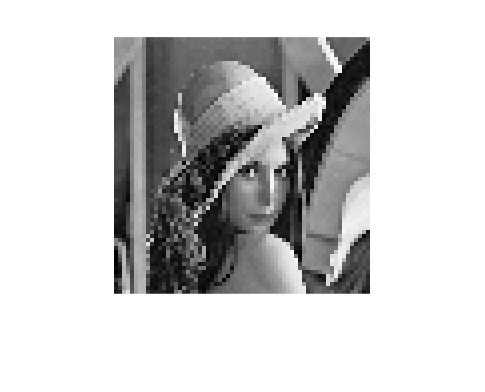

imshow(image1, [])

## GaussianSubsample-GaussianSubsample-supersample-supersample

tempimg4 = GaussianSubsample(img,2)

tempimg4 =    136   135   136   133   133   132   130   129   131   136   142   149   149   140   122    94    70    64    70    73    75    76    76    76    77    76    79    84    87    91    94    95    99    99   102   100    98    99    99   101   101   102   102   101   102   101   102   102   103   104
   135   134   134   131   131   130   129   128   130   135   143   148   148   139   119    92    68    62    67    72    73    74    74    74    75    75    78    83    87    91    93    94    97    98   100    99    98    99    99   100   101   102   102   101   101   101   100   101   102   102
   132   131   131   130   129   129   128   128   130   136   144   148   147   137   116    89    66    59    63    68    70    71    72    72    72    73    77    82    87    91    92    93    95    97    98    98    99    99    98    99    99   101   101   101   100   100   100   100   100   100
   131   130   130   130   130   129   128   129   133   140   145   146   144   134  

tempimg5 = GaussianSubsample(tempimg4,2)

tempimg5 =   135.0820  133.9860  131.9794  130.1691  132.5068  141.6836  142.8766  116.3493   78.3257   69.0380   73.4286   75.0949   75.9040   79.5991   86.9296   92.9761   97.2008   99.5689   98.9985   99.4529  100.9267  101.5369  101.2851  101.4109  102.3656  103.0505  102.6150  100.8772  100.6989  100.3933  100.9983  101.6544  101.6942   99.8966   98.9629   98.7690   97.6790   96.2136   92.4853   85.3220   86.2379  109.5813  129.0804  129.4202  127.8088  129.2621  127.9714  127.8697  129.9330  132.6411
  132.3476  131.4190  130.1039  129.2626  133.1303  141.9837  140.6593  112.9069   75.2753   65.5989   70.6664   72.5979   73.1186   77.8838   86.0428   91.8280   95.2373   97.6731   98.4972   98.7479   99.7871  100.5872  100.3437  100.0110  100.1949  100.3674  100.2158   99.2510   99.1200   99.0754   99.9292  100.1664   99.5407   98.2713   97.0459   96.6022   96.4257   95.7146   92.3399   85.0520   83.0993  102.0115  124.5329  130.4894  130.1466  130.9807  129.6356  128.6253  128.74

tempimg6 = supersample(tempimg5,2)

tempimg6 =   135.0820  135.0820  133.9860  133.9860  131.9794  131.9794  130.1691  130.1691  132.5068  132.5068  141.6836  141.6836  142.8766  142.8766  116.3493  116.3493   78.3257   78.3257   69.0380   69.0380   73.4286   73.4286   75.0949   75.0949   75.9040   75.9040   79.5991   79.5991   86.9296   86.9296   92.9761   92.9761   97.2008   97.2008   99.5689   99.5689   98.9985   98.9985   99.4529   99.4529  100.9267  100.9267  101.5369  101.5369  101.2851  101.2851  101.4109  101.4109  102.3656  102.3656
  135.0820  135.0820  133.9860  133.9860  131.9794  131.9794  130.1691  130.1691  132.5068  132.5068  141.6836  141.6836  142.8766  142.8766  116.3493  116.3493   78.3257   78.3257   69.0380   69.0380   73.4286   73.4286   75.0949   75.0949   75.9040   75.9040   79.5991   79.5991   86.9296   86.9296   92.9761   92.9761   97.2008   97.2008   99.5689   99.5689   98.9985   98.9985   99.4529   99.4529  100.9267  100.9267  101.5369  101.5369  101.2851  101.2851  101.4109  101.4109  102.36

image2 = supersample(tempimg6,2)

image2 =   135.0820  135.0820  135.0820  135.0820  133.9860  133.9860  133.9860  133.9860  131.9794  131.9794  131.9794  131.9794  130.1691  130.1691  130.1691  130.1691  132.5068  132.5068  132.5068  132.5068  141.6836  141.6836  141.6836  141.6836  142.8766  142.8766  142.8766  142.8766  116.3493  116.3493  116.3493  116.3493   78.3257   78.3257   78.3257   78.3257   69.0380   69.0380   69.0380   69.0380   73.4286   73.4286   73.4286   73.4286   75.0949   75.0949   75.0949   75.0949   75.9040   75.9040
  135.0820  135.0820  135.0820  135.0820  133.9860  133.9860  133.9860  133.9860  131.9794  131.9794  131.9794  131.9794  130.1691  130.1691  130.1691  130.1691  132.5068  132.5068  132.5068  132.5068  141.6836  141.6836  141.6836  141.6836  142.8766  142.8766  142.8766  142.8766  116.3493  116.3493  116.3493  116.3493   78.3257   78.3257   78.3257   78.3257   69.0380   69.0380   69.0380   69.0380   73.4286   73.4286   73.4286   73.4286   75.0949   75.0949   75.0949   75.0949   75.9040

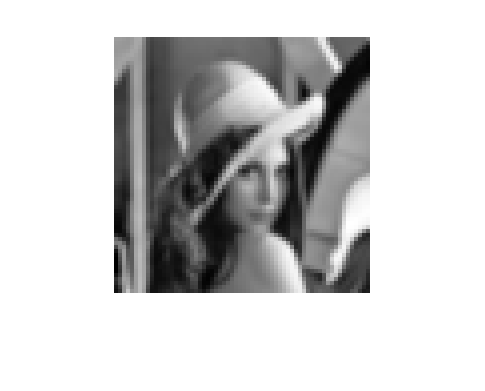

imshow(image2, [])

## GaussianSubsample-GaussianSubsample-GaussianSupersample-GaussianSupersample

tempimg7 = GaussianSubsample(img,2)

tempimg7 =    136   135   136   133   133   132   130   129   131   136   142   149   149   140   122    94    70    64    70    73    75    76    76    76    77    76    79    84    87    91    94    95    99    99   102   100    98    99    99   101   101   102   102   101   102   101   102   102   103   104
   135   134   134   131   131   130   129   128   130   135   143   148   148   139   119    92    68    62    67    72    73    74    74    74    75    75    78    83    87    91    93    94    97    98   100    99    98    99    99   100   101   102   102   101   101   101   100   101   102   102
   132   131   131   130   129   129   128   128   130   136   144   148   147   137   116    89    66    59    63    68    70    71    72    72    72    73    77    82    87    91    92    93    95    97    98    98    99    99    98    99    99   101   101   101   100   100   100   100   100   100
   131   130   130   130   130   129   128   129   133   140   145   146   144   134  

tempimg8 = GaussianSubsample(tempimg7,2)

tempimg8 =   135.0820  133.9860  131.9794  130.1691  132.5068  141.6836  142.8766  116.3493   78.3257   69.0380   73.4286   75.0949   75.9040   79.5991   86.9296   92.9761   97.2008   99.5689   98.9985   99.4529  100.9267  101.5369  101.2851  101.4109  102.3656  103.0505  102.6150  100.8772  100.6989  100.3933  100.9983  101.6544  101.6942   99.8966   98.9629   98.7690   97.6790   96.2136   92.4853   85.3220   86.2379  109.5813  129.0804  129.4202  127.8088  129.2621  127.9714  127.8697  129.9330  132.6411
  132.3476  131.4190  130.1039  129.2626  133.1303  141.9837  140.6593  112.9069   75.2753   65.5989   70.6664   72.5979   73.1186   77.8838   86.0428   91.8280   95.2373   97.6731   98.4972   98.7479   99.7871  100.5872  100.3437  100.0110  100.1949  100.3674  100.2158   99.2510   99.1200   99.0754   99.9292  100.1664   99.5407   98.2713   97.0459   96.6022   96.4257   95.7146   92.3399   85.0520   83.0993  102.0115  124.5329  130.4894  130.1466  130.9807  129.6356  128.6253  128.74

tempimg9 = GaussianSupersample(tempimg8,2)

tempimg9 =   133.5090  133.5090  132.7249  132.7249  131.9620  131.9620  132.4357  132.4357  134.7309  134.7309  135.7012  135.7012  128.5240  128.5240  110.4279  110.4279   89.4047   89.4047   76.3595   76.3595   72.9228   72.9228   73.9768   73.9768   76.5010   76.5010   80.5733   80.5733   85.9793   85.9793   91.2832   91.2832   95.2690   95.2690   97.6214   97.6214   98.7527   98.7527   99.4593   99.4593  100.1503  100.1503  100.6590  100.6590  100.8941  100.8941  101.0916  101.0916  101.3721  101.3721
  133.5090  133.5090  132.7249  132.7249  131.9620  131.9620  132.4357  132.4357  134.7309  134.7309  135.7012  135.7012  128.5240  128.5240  110.4279  110.4279   89.4047   89.4047   76.3595   76.3595   72.9228   72.9228   73.9768   73.9768   76.5010   76.5010   80.5733   80.5733   85.9793   85.9793   91.2832   91.2832   95.2690   95.2690   97.6214   97.6214   98.7527   98.7527   99.4593   99.4593  100.1503  100.1503  100.6590  100.6590  100.8941  100.8941  101.0916  101.0916  101.37

image3 = GaussianSupersample(tempimg9,2)

image3 =   133.3270  133.3270  133.1396  133.1396  132.8258  132.8258  132.4849  132.4849  132.2227  132.2227  132.1973  132.1973  132.5019  132.5019  133.1748  133.1748  134.0765  134.0765  134.7543  134.7543  134.6759  134.6759  132.9716  132.9716  129.1282  129.1282  122.8513  122.8513  114.4099  114.4099  104.8645  104.8645   95.2060   95.2060   86.8551   86.8551   80.4633   80.4633   76.3077   76.3077   74.1907   74.1907   73.4978   73.4978   73.7907   73.7907   74.6511   74.6511   75.9236   75.9236
  133.3270  133.3270  133.1396  133.1396  132.8258  132.8258  132.4849  132.4849  132.2227  132.2227  132.1973  132.1973  132.5019  132.5019  133.1748  133.1748  134.0765  134.0765  134.7543  134.7543  134.6759  134.6759  132.9716  132.9716  129.1282  129.1282  122.8513  122.8513  114.4099  114.4099  104.8645  104.8645   95.2060   95.2060   86.8551   86.8551   80.4633   80.4633   76.3077   76.3077   74.1907   74.1907   73.4978   73.4978   73.7907   73.7907   74.6511   74.6511   75.9236

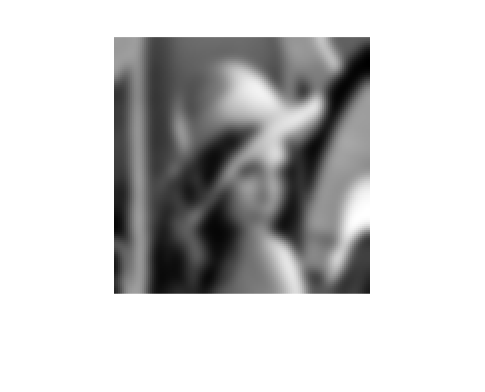

imshow(image3, [])

## edge detection

edge1 = edgedetection(image1)

edge1 = 256×256 logical 数组
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0 

edge2 = edgedetection(image2)

edge2 = 256×256 logical 数组
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1   1   1   0   0   0   0   0   0   0   0 

edge3 = edgedetection(image3)

edge3 = 256×256 logical 数组
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

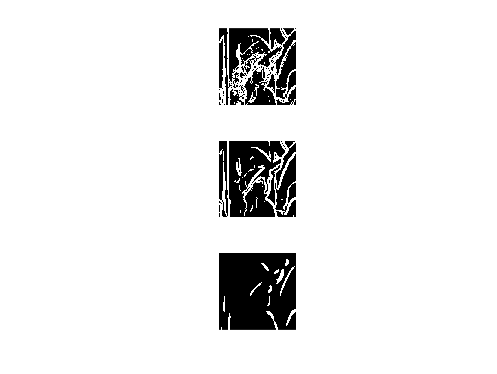


figure
subplot(311)
imshow(edge1,[])
subplot(312)
imshow(edge2,[])
subplot(313)
imshow(edge3,[])

## FFT

spectrum1 = spectrum(image1)

spectrum1 = 	1.0e+13 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

spectrum2 = spectrum(image2)

spectrum2 = 	1.0e+13 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

spectrum3 = spectrum(image3)

spectrum3 = 	1.0e+13 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

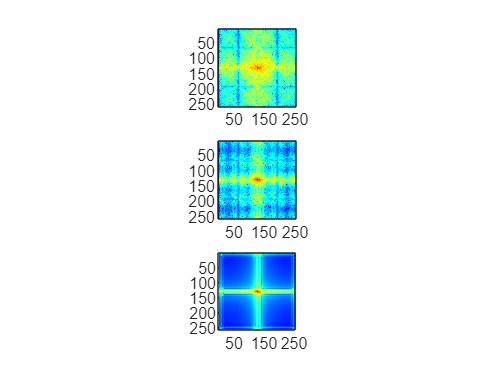


figure
subplot(311)
imagesc(log(1 + spectrum1))
axis image
colormap(gca, 'jet')
subplot(312)
imagesc(log(1 + spectrum2))
axis image
colormap(gca, 'jet')
subplot(313)
imagesc(log(1 + spectrum3))
axis image
colormap(gca, 'jet')